# Sistemas de Visión Artificial

# **Práctica 1. Parte 2. Ejemplo de detector de movimiento**

**Autor(es): Alejandro Fernandez Ambros, Cristina Martinez Toledo**

**Fecha: 28/09/2026**

Analice el código del siguiente detector de movimiento e incluya alguna de las modificaciones realizada sobre la captura en el imageAcquisitionExplorer (cambio de tamaño de la imagen, definición de ROI, brillo, contraste, etc.).

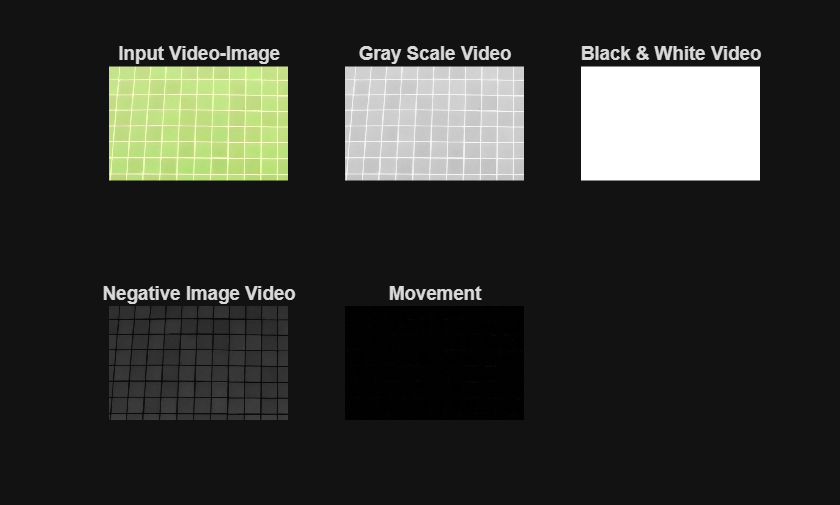


clear all
close all

clc
vid = videoinput('winvideo', 1);
set(vid,'TriggerRepeat',Inf);
vid.FrameGrabInterval = 5;


%*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*
vid.ReturnedColorspace = "rgb";
vid.ROIPosition = [81 22 488 311];

src = getselectedsource(vid);
src.Brightness = -37;
src.Contrast = 56;
src.Gamma = 181;
src.Hue = 40;
src.Saturation = 84;
src.Sharpness = 1;
src.WhiteBalance = 4563;
src.WhiteBalanceMode = "manual";
%*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*

start(vid);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
try
    while(vid.FramesAcquired<=110) % Stop after 110 frames
        IM = getdata(vid,2);
        IMGray = rgb2gray(IM(:,:,1:3));
        IMbw=im2bw(IMGray,0.5);
        IMneg=imadjust(IMGray,[0 1],[1 0]);
        subplot(2,3,1);imshow(IM(:,:,:,1));title('Input Video-Image')
        subplot(2,3,2);imshow(IMGray);title('Gray Scale Video')
        subplot(2,3,3);imshow(IMbw);title('Black & White Video')
        subplot(2,3,4);imshow(IMneg);title('Negative Image Video')

        i1=IM(:,:,:,1);
        i2=IM(:,:,:,2);
        i1=rgb2gray(i1(:,:,1:3));
        i2=rgb2gray(i2(:,:,1:3));
        m=abs(double(i1)-double(i2))/256;
        subplot(2,3,5);imshow(m);title('Movement')
    end
    stop(vid);
    %%%%%%%%%%%%%%%%%%%%%%
catch ME
    stop(vid);
    disp(ME.message)
end

La **entrega correspondiente a la parte 2 de la práctica 1 **será este mlx modificado para incluir la modificación varios parámetros de la captura (ROI, brillo, etc...), incluyendo en la parte superior, en el espacio reservado para ello, el nombre de los autores y la fecha.